set(0,'DefaultTextFontname', 'LM Roman 9')
set(0,'DefaultAxesFontName', 'LM Roman 9')

pidx = [2,3];

preds_path = "C:\.matlab_workspace\.data\ct_mask_preds\";
truth_path = "C:\.matlab_workspace\.data\ct_pt_volumes\";

truth = load(truth_path + "patient" + pidx(1) + "_day" + pidx(2) + ".mat", "stern_mask");
truth = truth.stern_mask;
truth = logical(truth);
axial_pred = load(preds_path + "patient" + pidx(1) + "_day" + pidx(2) + "_pred.mat", "stern");
axial_pred = axial_pred.stern;
axial_pred = axial_pred > 0.5;

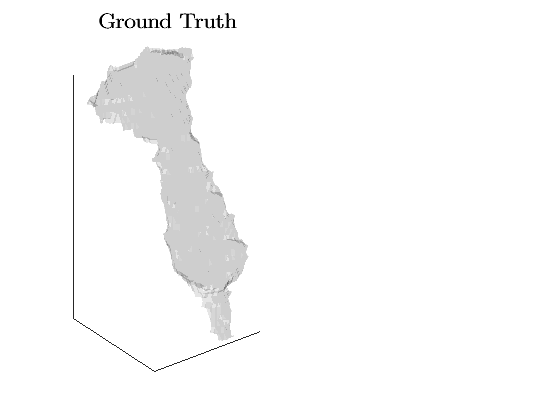

figure();
subplot(1,2,1);
pred_vol = truth;
intersection = pred_vol .* truth;
false_neg_vol = truth - intersection;
false_pos_vol = pred_vol - intersection;
fv0 = isosurface(pred_vol, .9);
fv1 = isosurface(false_neg_vol, .9);
fv2 = isosurface(false_pos_vol, .9);
p0 = patch(fv0, 'FaceColor', 'black', 'CDataMapping', 'scaled', 'EdgeColor','none');
p0.FaceAlpha = .1;
p1 = patch(fv1, 'FaceColor', 'blue', 'CDataMapping', 'scaled', 'EdgeColor','none');
p1.FaceAlpha = .2;
p2 = patch(fv2, 'FaceColor', 'red', 'CDataMapping', 'scaled', 'EdgeColor','none');
p2.FaceAlpha = .4;
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-80)
lighting flat
title("\fontsize{16}Ground Truth")
xlims = get(gca, 'XLim');
ylims = get(gca, 'YLim');
zlims = get(gca, 'ZLim');
set(gca, 'XTickLabel', [], 'YTickLabel', [], 'ZTickLabel', [], ...
         'XTick', [], 'YTick', [], 'ZTick', []);

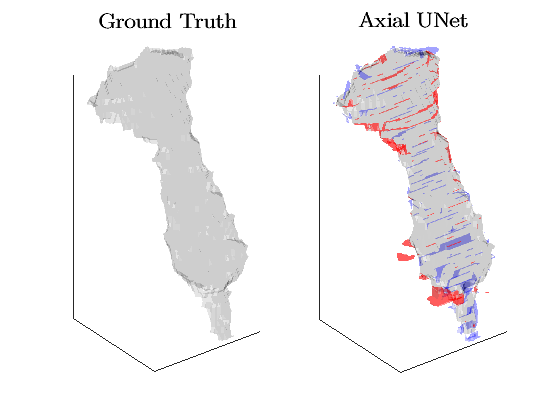

subplot(1,2,2);
pred_vol = axial_pred;
intersection = pred_vol .* truth;
false_neg_vol = truth - intersection;
false_pos_vol = pred_vol - intersection;
fv0 = isosurface(pred_vol, .9);
fv1 = isosurface(false_neg_vol, .9);
fv2 = isosurface(false_pos_vol, .9);
p0 = patch(fv0, 'FaceColor', 'black', 'CDataMapping', 'scaled', 'EdgeColor','none');
p0.FaceAlpha = .1;
p1 = patch(fv1, 'FaceColor', 'blue', 'CDataMapping', 'scaled', 'EdgeColor','none');
p1.FaceAlpha = .2;
p2 = patch(fv2, 'FaceColor', 'red', 'CDataMapping', 'scaled', 'EdgeColor','none');
p2.FaceAlpha = .4;
view(3)
daspect([1,1,1/3])
axis tight
camlight
camlight(-80,-80)
lighting flat
title("\fontsize{16}Axial UNet")
set(gca, 'XLim', xlims, 'YLim', ylims, 'ZLim', zlims, 'XTickLabel', [], 'YTickLabel', [], 'ZTickLabel', [], ...
         'XTick', [], 'YTick', [], 'ZTick', []);